close all
% syms Ks Km Jm Jl x1 x2 x3 x4 x5 m g l Ra La b
% eqn1 = 0 == -Ks/Jm * x1 + Ks/Jm * x2 + Km/Jm * x5
% eqn2 = 0 == Ks/Jl * x1 - Ks/Jl -m*g*L*sin(x2)/Jl
% eqn3 = 0 == -Ra/La * x5;
% 
% solve([eqn1,eqn2], [x1,x2])

% Motor 1 parameters
Jm = 0.0021

Jm = 0.0021

Ra = 2.6

Ra = 2.6000

La = 0.18*10^-3

La = 1.8000e-04

Km =  0.5369

Km = 0.5369


% Motor 2 parameters
% Jm = 7.5e-6
% Ra = 2
% La = 1.3e-3
% Km = 27e-3

% Tune for system
Ks = 1.55 % [1.55, 1.80]

Ks = 1.5500

b = 0.013 %  [0.013, 0.019]

b = 0.0130

x2e = deg2rad(45);

Jl = 0.001;
m = 0.1;
g = 9.81;
l = 0.1;


% Linearise at 45 degrees
A = [0 0 1 0 0;
    0 0 0 1 0;
    -Ks/Jm Ks/Jm 0 0 Km/Jm;
    Ks/Jl -Ks/Jl-m*g*l*cos(x2e)/Jl 0 0 0;
    0 0 -Km/La 0 -Ra/La]

A = 1.0e+04 *

         0         0    0.0001         0         0
         0         0         0    0.0001         0
   -0.0738    0.0738         0         0    0.0256
    0.1550   -0.1619         0         0         0
         0         0   -0.2983         0   -1.4444



% Linearise at 0 degrees
% A = [0 0 1 0 0;
%     0 0 0 1 0;
%     -Ks/Jm Ks/Jm 0 0 Km/Jm;
%     Ks/Jl -Ks/Jl-(m*g*l/Jl) 0 0 0;
%     0 0 -Km/La 0 -Ra/La]

B = [0;0;0;0;1/La]

B = 1.0e+03 *

         0
         0
         0
         0
    5.5556



C = [0 1 0 0 0]

C =      0     1     0     0     0



D = 0

D = 0



SqWaveFreq = 5

SqWaveFreq = 5

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.





G = C*inv((s*eye(5) - A))*B + D

G =
 
                                 2.202e09
  -----------------------------------------------------------------------
  s^5 + 1.444e04 s^4 + 7.65e05 s^3 + 3.405e07 s^2 + 1.235e09 s + 7.395e08
 
Continuous-time transfer function.



num = [G.Numerator{:}]

num = 1.0e+09 *

         0         0         0         0         0    2.2016


den = [G.Denominator{:}]

den = 1.0e+09 *

    0.0000    0.0000    0.0008    0.0341    1.2350    0.7395


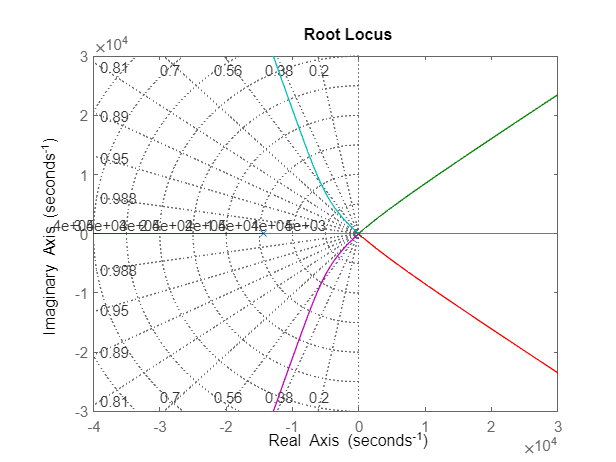

controlSystemDesigner(G);

figure();
rlocus(G)
hold on
grid on


% Settling Time requirements
